clear
clc
close all

help eig

help cov


%Generate the dataset
dataset = randn(50,500);

%Calculate the mean
mean_vector = mean(dataset,2);

%Zero mean the dataset by subtracting the mean
zero_dataset = dataset - mean_vector;

%Calculate the covariance matrix for the zero dataset
covariance = cov(zero_dataset');  % V·V'

%Compute variance for each dimension
[eigenvectors, eigenvalues] = eig(covariance);  % eigendecomposition

eigenvalues = diag(eigenvalues);
[~, idx] = sort(eigenvalues, 'descend');
eigenvalues = eigenvalues(idx);
eigenvectors = eigenvectors(:, idx);



%Initialise errors and eigenvalue-percentages arrays
max_q = size(dataset,1)

max_q = 50

errors = zeros(1,max_q);


- Eigenvalues: Eigenvalues are scalar values that represent the amount of variance explained by each principal component. They indicate the "importance" or magnitude of each principal component. Higher eigenvalues correspond to principal components that capture more information from the original data.

- Eigenvectors: Eigenvectors are vectors that represent the direction or orientation of each principal component. Each eigenvector is associated with an eigenvalue and defines the principal component in the feature space. The length or magnitude of an eigenvector does not matter; only its direction is significant.

2.协方差矩阵

3.求出协方差矩阵的特征值及对应的特征向量

4.将特征向量按对应特征值大小从上到下按行排列成矩阵，取前k行组成矩阵P

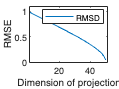


for q=1:max_q   % select q feature value/eigen value
    
    %Compute the reduced eigenvalues and eigenvectors of the covariance matrix
    reduced_eigenvalues = eigenvalues(1:q);
    reduced_eigenvectors = eigenvectors(:, 1:q);

    
%     %Compute the percentage of variance captured by subspace
%     var_sub = sum_largest_values/sum_eigvalues; %越趋近于1，两者越接近
%     var_subs(1,q) = var_sub;
    
    %Compute transpose of reduced eigenvectors
%     E_T = E';
    
    %Reduce the dataset by multipling with E_T
    reduced_data = reduced_eigenvectors' * dataset;
    reconstructed_data = reduced_eigenvectors * reduced_data + mean_vector;
    
%     %Generate new dataset from reduced dataset
%     new_dataset_zerod = E*reduced_dataset;
%     new_dataset = new_dataset_zerod + mean_vector;
    
    %Estimate the error
%     RMSD = (sqrt(mean(mean((dataset-new_dataset).^2))));
    RMSD = sqrt(mean(mean((dataset - reconstructed_data).^2)));
    
    errors(1,q) = RMSD;
end


%Plotting RMSD for different q-values
plot(errors);

hold on;
xlabel('Dimension of projection')
ylabel('RMSE')
xlim([1 51]);
ylim([0 1.1]);
legend({'RMSD'},'Location','northeast')
hold off;

Choles vs random

clear
clc
close all

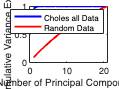

load choles_all;

data = p;

%choles data
covariance = cov(data');
[eigenvectors, eigenvalues] = eig(covariance);
eigenvalues = diag(eigenvalues);
[~, idx] = sort(eigenvalues, 'descend');
eigenvalues = eigenvalues(idx);
eigenvectors = eigenvectors(:, idx);
cumulative_variance = cumsum(eigenvalues) / sum(eigenvalues);

% random data
random_data = randn(size(data));
random_covariance = cov(random_data');
[random_eigenvectors, random_eigenvalues] = eig(random_covariance);
random_eigenvalues = diag(random_eigenvalues);
[~, random_idx] = sort(random_eigenvalues, 'descend');
random_eigenvalues = random_eigenvalues(random_idx);
random_eigenvectors = random_eigenvectors(:, random_idx);


% Calculate the root mean square error (RMSE) between original and reconstructed data
num_components = 1:size(eigenvalues, 1);
rmse = zeros(size(num_components));
random_rmse = zeros(size(num_components));

for i = 1:length(num_components)
    reduced_data = eigenvectors(:, 1:num_components(i))' * data;
    reconstructed_data = eigenvectors(:, 1:num_components(i)) * reduced_data;
    rmse(i) = sqrt(mean(mean((data - reconstructed_data).^2)));
    
    random_reduced_data = random_eigenvectors(:, 1:num_components(i))' * random_data;
    random_reconstructed_data = random_eigenvectors(:, 1:num_components(i)) * random_reduced_data;
    random_rmse(i) = sqrt(mean(mean((random_data - random_reconstructed_data).^2)));
end

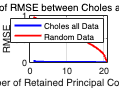


% Plot the RMSE values
figure;
plot(num_components, rmse, 'b-', 'LineWidth', 2);
hold on;
plot(num_components, random_rmse, 'r-', 'LineWidth', 2);
hold off;
xlabel('Number of Retained Principal Components');
ylabel('RMSE');
title('Comparison of RMSE between Choles and Random Data');
legend('Choles all Data', 'Random Data');
grid on;